% =========================================================================
%                CONFIGURACIÓN DEL MODELO DEL MOTOR DC
% =========================================================================
% Este bloque define los parámetros del motor y analiza su comportamiento
% en lazo abierto y cerrado, tanto en tiempo continuo como discreto.
% =========================================================================

% Parámetros del motor
Ra = 15.6;         % Resistencia del motor (Ω)
La = 1.2e-3;       % Inductancia del motor (H)
J = 0.000013238;   % Inercia del rotor (kg*m^2)
B = 0.00033333;    % Coeficiente de fricción viscosa (N*m*s)
Km = 0.267783701;  % Constante de par del motor (N*m/A)
Ka = 0.267783701;  % Constante de fuerza contraelectromotriz (V*s/rad)

% Definición de la función de transferencia continua
s = tf('s');
num = Km;
den = s * (La * J * s^2 + (Ra * J + La * B) * s + (Ra * B + Km * Ka));

% Función de transferencia de la planta (Motor DC)
disp('Función de transferencia lazo abierto del motor DC (Continua):')

Función de transferencia lazo abierto del motor DC (Continua):


G = num / den

G =
 
                   0.2678
  -----------------------------------------
  1.589e-08 s^3 + 0.0002069 s^2 + 0.07691 s
 
Continuous-time transfer function.
Model Properties



% Función de transferencia en lazo cerrado (retroalimentación unitaria)
disp('Función de transferencia lazo cerrado del motor DC (Continua):')

Función de transferencia lazo cerrado del motor DC (Continua):


G1 = feedback(G, 1)

G1 =
 
                        0.2678
  --------------------------------------------------
  1.589e-08 s^3 + 0.0002069 s^2 + 0.07691 s + 0.2678
 
Continuous-time transfer function.
Model Properties


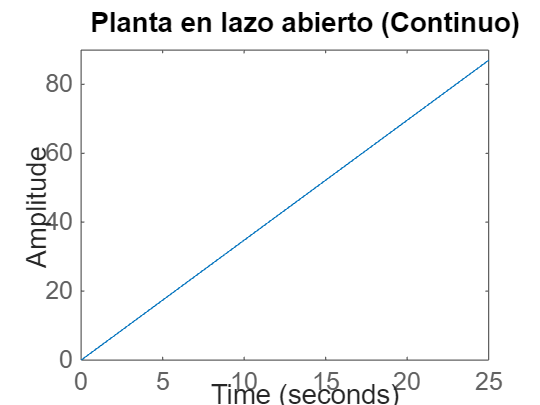

% --- Gráficas del sistema continuo ---
figure;
grid on;
step(G);
title("Planta en lazo abierto (Continuo)");

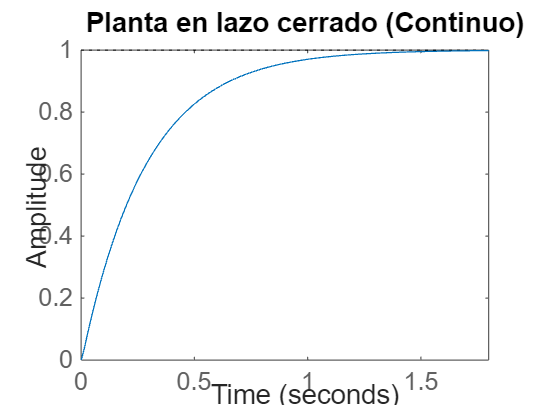

figure;
grid on;
step(G1);
title("Planta en lazo cerrado (Continuo)");

% Discretización de la planta
Ts = 0.01; % Tiempo de muestreo
disp('Función de transferencia lazo abierto (Discreta):')

Función de transferencia lazo abierto (Discreta):


G_z = c2d(G, Ts, 'tustin');

% Función de transferencia discreta en lazo cerrado
disp('Función de transferencia lazo cerrado (Discreta):')

Función de transferencia lazo cerrado (Discreta):


G1_z = feedback(G_z, 1)

G1_z =
 
  0.01126 z^3 + 0.03378 z^2 + 0.03378 z + 0.01126
  -----------------------------------------------
    1.011 z^3 + 0.3165 z^2 - 0.9449 z - 0.2928
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


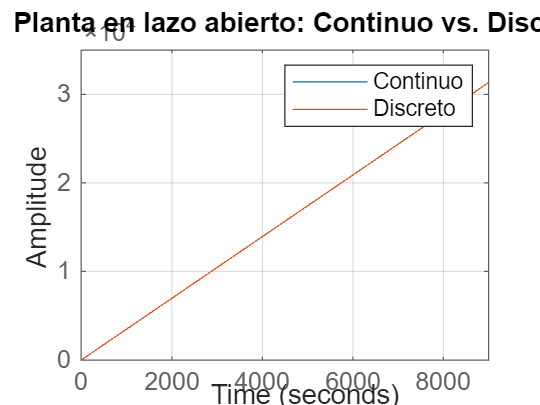

% --- Gráficas de comparación Continuo vs. Discreto ---
figure;
step(G);
hold on;
step(G_z);
hold off;
grid on;
title('Planta en lazo abierto: Continuo vs. Discreto');
legend('Continuo', 'Discreto');

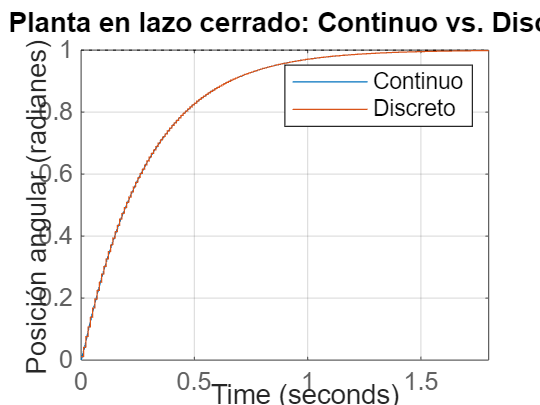

figure;
step(G1);
hold on;
step(G1_z);
hold off;
grid on;
title('Planta en lazo cerrado: Continuo vs. Discreto');
ylabel('Posición angular (radianes)');
legend('Continuo', 'Discreto');

% Extracción de datos de la función de transferencia discreta
NumZ = G_z.Numerator{1};   % Coeficientes del numerador
DenZ = G_z.Denominator{1};   % Coeficientes del denominador
[z, p, k] = zpkdata(G_z, 'v'); % Ceros, polos y ganancia

% =========================================================================
%                  CONFIGURACIÓN DEL CONTROLADOR PID
% =========================================================================
% Este bloque define un controlador PID discreto y analiza el
% comportamiento del sistema en lazo cerrado con dicho controlador.
% =========================================================================

% Coeficientes del controlador PID
P = 1.8003719;
I = 2.0320928;
D = -0.0290880;
N = 49.7413281; % Coeficiente del filtro derivativo

% Término Proporcional
C_p = tf(P, 1, Ts);

% Término Integral: I*Ts / (z - 1)
C_i = tf(I * Ts, [1 -1], Ts);

% Término Derivativo con filtro: (D*N)*(z - 1) / (z - 1 + N*Ts)
num_d = D * N * [1 -1];       % Numerador: D*N*(z - 1)
den_d = [1, (N * Ts - 1)];    % Denominador: (z - 1 + N*Ts)
C_d = tf(num_d, den_d, Ts);

% Controlador PID completo (suma de los términos)
disp('Función de transferencia PID discreta:')

Función de transferencia PID discreta:


C_pid = C_p + C_i + C_d

C_pid =
 
  0.3535 z^2 + 0.2089 z - 0.5522
  ------------------------------
      z^2 - 1.503 z + 0.5026
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties




% Sistema en lazo cerrado con el controlador PID
disp('Función de transferencia del sistema controlado:')

Función de transferencia del sistema controlado:


T = feedback(C_pid * G_z, 1)

T =
 
  0.00398 z^5 + 0.01429 z^4 + 0.01278 z^3 - 0.007618 z^2 - 0.0163 z - 0.006217
  ----------------------------------------------------------------------------
       1.004 z^5 - 1.206 z^4 - 0.888 z^3 + 1.301 z^2 - 0.05127 z - 0.159
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


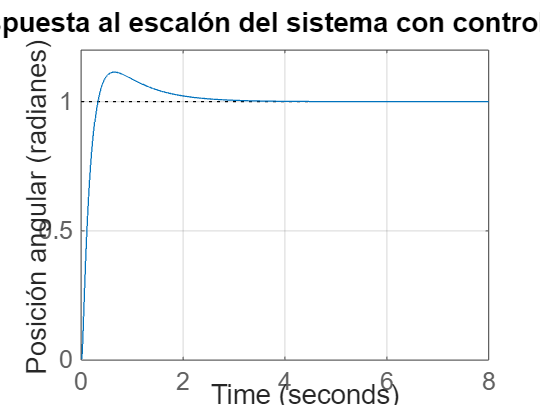


% --- Gráfica del sistema controlado ---
figure;
step(T);
grid on;
title('Respuesta al escalón del sistema con controlador PID');
ylabel('Posición angular (radianes)');